# Full Wave Simulator

Converts LTSPICE .txt files to a MATLAB Matrix and plots

## Directory and Internal Libraries/Functions

Sets paths easily to run, calling functions that import different data types

computer = "PC";
if (strcmp(computer, 'PC')) % PC
    %cd 'G:\My Drive\Code\LTSpice\200630 xGAN xGEM Load Responses V0';
    cd 'C:\Users\johns\Documents\Github\Gated-Mirror_xGANxSCAxGEM\200801 xGAN Full Module v1'
    addpath( 'G:\My Drive\Code\LTSpice\200825 xGAN xGEM Load Responses V1\', ...  % LT Spice output response
        'C:\Users\johns\Documents\Github\Gated-Mirror_xGANxSCAxGEM\200801 xGAN Full Module v1',...
        'C:\Users\johns\Documents\Github\QEM-MATLAB\Data Converters\LTSpice_Converter', ... % LT Spice reader from Github
        'C:\Users\johns\Documents\Github\QEM-MATLAB', ...    % Access to generic libraries
        'G:\My Drive\Code\COMSOL\xGAN Gated Mirror Sims\Export'); %new comsol stuff
    
elseif (strcmp(computer, 'Mac'))
    %cd 'C:\Users\johns\Documents\Github\QEM-MATLAB\Data Converters\LTSpice_Converter'
    addpath('/Volumes/GoogleDrive/My Drive/Code/Github Failed MATLAB 200807/QEM-MATLAB/Data Converters/LTSpice_Converter', ...
        '/Volumes/GoogleDrive/My Drive/Code/Github Failed MATLAB 200807/QEM-MATLAB', ...
        '/Volumes/GoogleDrive/My Drive/Code/Github Failed MATLAB 200807/Gated-Mirror_xGANxSCAxGEM/200801 xGAN Full Module v1');
end

load('ImpVariables.mat')

## Generate Impedance Response of Load

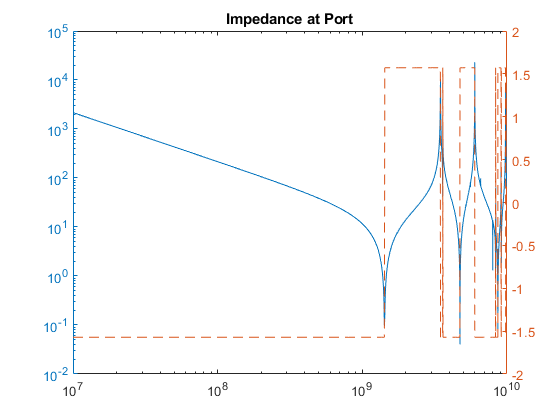

% Workbook for impedance math in "C:\Users\johns\Documents\Github\Gated-Mirror_xGANxSCAxGEM\200801 xGAN Full Module v1"
% Result is plotted
clf
port = ImportCOMSOL_Z('Kimball_Impedance.txt');
yyaxis left
loglog(port.freq, abs(port.z))
yyaxis right
semilogx(port.freq, unwrap(angle(port.z)),'LineStyle',"--");
title('Impedance at Port')
hold off


ratFitS = rationalfit(port.freq, port.s11);
generateSPICE(ratFitS, 'JWS_TestNetwork_v0.ckt');

## Time Domain Constant step exporter

Takes data from batch files in LTSpice and exports

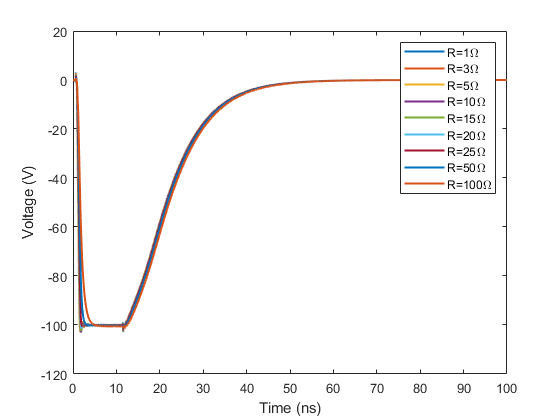

name = '200825 xGAN Kimball Circuit Resetting.txt';
timeRes = 1/20e9; % 20GHz total BW (10Ghz positive)
interpMethod = 'linear'; %pchip linear
[stepR,interpTime, interpVoltAll] = ImportLTSpiceSweep(name, timeRes, interpMethod);

% Plots out result read from file to check
figure()
plot(interpTime/c.nano, interpVoltAll, "LineWidth", 1.5); xlabel('Time (ns)'); ylabel('Voltage (V)')
rNames = string(stepR);
legend('R=' + rNames +'\Omega')

save("200825 xGAN Kimball Circuit Resetting.mat", "stepR", "interpTime", "interpVoltAll");

## Convert COMSOL Transfer Function 

filename='Kimball_TF.txt';
makeSymmetric = 1;
[rawTF, symTF] = ImportCOMSOL_TF(filename, port.v, makeSymmetric);

comsolFreqStep = 10000000

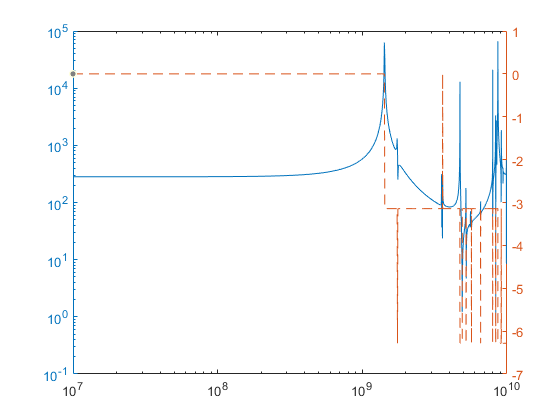

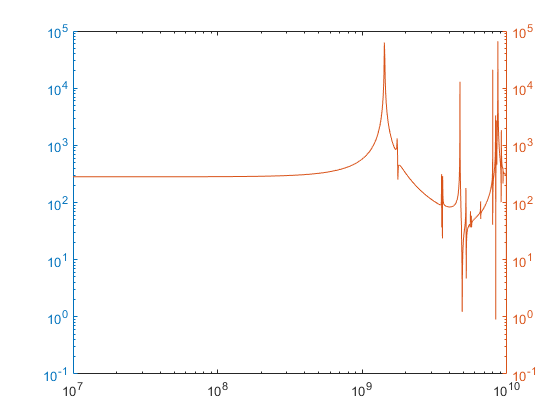


clf;
% Look at transfer Function
yyaxis left
loglog(rawTF.freq,abs(rawTF.fieldTF))
yyaxis right
semilogx(rawTF.freq, unwrap(angle(rawTF.fieldTF)),'LineStyle',"--");

% Check symmetry of fields
semilogy(symTF.freq,abs(symTF.fieldTF))

## Generate and Plot LTSpice Output FT

resIndex = 7;
[time, signal, freq, fftSignal] = dummyFunction('Custom', 1/20e9, 10*c.mega,  interpTime, interpVoltAll(resIndex,:))

time = 	1.0e+-7 *

         0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245


signal =    -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.5063   -0.2434    1.7797    1.1563   -0.1494   -0.3123   -0.5106   -2.0958   -4.2958   -9.1147  -14.8261  -20.5102  -25.1351  -30.0653  -36.6245  -44.1095  -51.6698  -58.9421  -66.4081  -73.5481  -79.6884  -84.2536  -88.0851  -91.5635  -94.5759  -96.9027  -98.5460  -99.4643  -99.9481 -100.2992 -100.4729 -100.5443 -100.4674 -100.3958 -100.3831 -100.3151 -100.2803 -100.2182 -100.1671


freq = 	1.0e+10 *

   -1.0000   -0.9990   -0.9980   -0.9970   -0.9960   -0.9950   -0.9940   -0.9930   -0.9920   -0.9910   -0.9900   -0.9890   -0.9880   -0.9870   -0.9860   -0.9850   -0.9840   -0.9830   -0.9820   -0.9810   -0.9800   -0.9790   -0.9780   -0.9770   -0.9760   -0.9750   -0.9740   -0.9730   -0.9720   -0.9710   -0.9700   -0.9690   -0.9680   -0.9670   -0.9660   -0.9650   -0.9640   -0.9630   -0.9620   -0.9610   -0.9600   -0.9590   -0.9580   -0.9570   -0.9560   -0.9550   -0.9540   -0.9530   -0.9520   -0.9510


fftSignal = 	1.0e+04 *

  -4.4173 + 0.0000i  -2.5053 + 2.8031i  -0.1425 + 2.5129i   0.5803 + 1.3797i   0.5011 + 0.7067i   0.3177 + 0.4596i   0.2240 + 0.3922i   0.2075 + 0.3609i   0.2197 + 0.3202i   0.2311 + 0.2714i   0.2351 + 0.2242i   0.2348 + 0.1820i   0.2316 + 0.1432i   0.2238 + 0.1071i   0.2106 + 0.0763i   0.1946 + 0.0537i   0.1807 + 0.0390i   0.1719 + 0.0281i   0.1673 + 0.0165i   0.1635 + 0.0019i   0.1569 - 0.0146i   0.1466 - 0.0301i   0.1337 - 0.0423i   0.1205 - 0.0505i   0.1087 - 0.0556i   0.0991 - 0.0593i   0.0911 - 0.0630i   0.0836 - 0.0673i   0.0757 - 0.0721i   0.0668 - 0.0765i   0.0569 - 0.0798i   0.0468 - 0.0813i   0.0371 - 0.0811i   0.0286 - 0.0796i   0.0215 - 0.0776i   0.0153 - 0.0758i   0.0095 - 0.0744i   0.0036 - 0.0731i  -0.0027 - 0.0714i  -0.0091 - 0.0689i  -0.0151 - 0.0654i  -0.0202 - 0.0612i  -0.0244 - 0.0566i  -0.0276 - 0.0521i  -0.0302 - 0.0479i  -0.0325 - 0.0441i  -0.0348 - 0.0404i  -0.0371 - 0.0365i  -0.0392 - 0.0324i  -0.0408 - 0.0278i


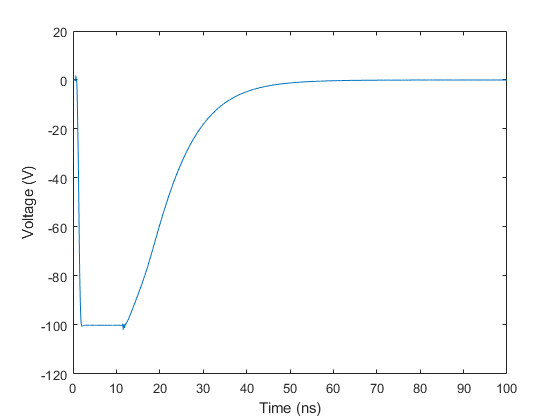

plot(time/c.nano, signal); xlabel("Time (ns)"); ylabel("Voltage (V)");

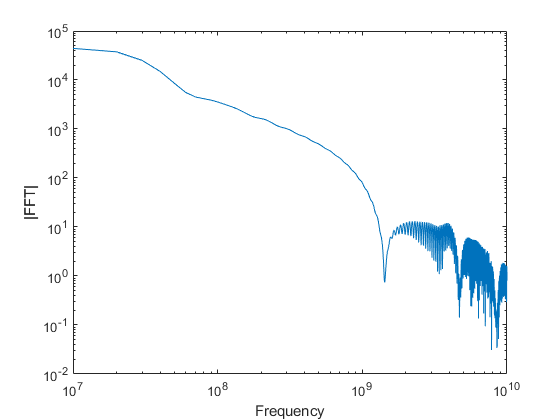


loglog(freq(end/2+1:end), abs(fftSignal(1:end/2))); xlabel("Frequency"); ylabel("|FFT|");

## Generate Fourier Transform of LTSpice Output

workspaceName='200825 xGAN Symmetric Kimball Sweep v4.mat';
load(workspaceName);
r=7;%which damping resistor
vLoadRaw=transpose(interpVoltAllDbl(r,:));
timeRaw=transpose(interpTimeDbl);
% time=downsample(timeRaw,5);
% vLoad=downsample(vLoadRaw,5);
time=decimate(timeRaw,7);% thie
vLoad=decimate(vLoadRaw,7);

T=mean(diff(time)); %time iterations
BW=1/(2*T);
Fs=1/T; %sampling frequency
L=length(time);
padLength=floor(L/2)*100;
[trash,midVidx]=min(abs(vLoad-mean(vLoad)));
shift=floor(L/2)-midVidx;
padFront=vLoad(1)*ones(shift+padLength/2,1);
padEnd=vLoad(end)*ones(-shift+padLength/2,1);
vLoadPad=[padFront;vLoad;padEnd];
timePad=T*transpose(0:length(vLoadPad)-1);
Lpad=length(timePad);
fPos=(0:(Lpad/2-1))*(Fs/Lpad);
fNeg=((-Lpad/2):-1)*(Fs/Lpad);
f=transpose([0:Lpad/2-1, -Lpad/2:-1]*(Fs/Lpad));
vLoadTF=fft(vLoadPad,length(f));

## Extra Functions

if(0) % shuts off everything below here

## Code from GitHub

[https://github.com/PeterFeicht/ltspice2matlab.git](https://github.com/PeterFeicht/ltspice2matlab.git)

    % Very nice converter from Github!!
    
    % !!!!!!!!!!! Can NOT do steps.. sadly !!!!!!!!!!
    
    addpath('C:\Users\johns\Documents\Github\ltspice2matlab')
    addpath('G:\My Drive\Code\LTSpice\200630 xGAN xGEM Load Responses V0')
    % function raw_data = LTspice2Matlab( filename, varargin )
    %    Calling Convention:
    %        RAW_DATA = LTspice2Matlab( FILENAME );                  % Returns all variables found in FILENAME
    %                             (or)
    %        RAW_DATA = LTspice2Matlab( FILENAME, SELECTED_VARS );   % Returns only selected variables
    %               Set SELECTED_VARS to [] to quickly determine the number and names of variables present in
    %               FILENAME without actually loading the variables.
    %                             (or)
    %        RAW_DATA = LTspice2Matlab( FILENAME, SELECTED_VARS, N );
    %               Returns variables listed in SELECTED_VARS, with all waveforms downsampled by N. Set N > 1 to
    %               load very large data files using less memory, at the price of degraded waveform accuracy and
    %               possible aliasing.
    
    filename = '200728 xGAN Kimball Circuit v1.raw'
    % rawData = LTspice2Matlab( filename, [] )
    
    rawData = LTspice2Matlab( filename, [10])
    
    rawData.variable_name_list % V(n005) is column 10
    
    time = rawData.time_vect;
    voltage = rawData.variable_mat;
    plot(time, voltage)
    
    % R = 20;
    % RString = num2str(R);
    % saveName = "KimbalDampingR" + RString +'.mat';
    % save(saveName, 'time', 'voltage')

## Interpolate to constant time step!

    % timeRes = 10E-12; % 10ps time resolution
    % interpTime = linspace(time(1), time(end), (time(end)-time(1))/timeRes+1);
    % interpVolt = interp1(time,voltage,interpTime, 'PCHIP');
    %
    % figure(2)
    % titleText = ['Interpolated File ', name];
    % plot(interpTime, interpVolt);
    % title(titleText);
    % xlabel(tit1);
    % ylabel(tit2);
    

## Original Method Direct Read

    % % Checks data from current directory with frequency data
    % Files = dir;
    % checkThis = 2; % which file to read/look at
    % name = Files(checkThis).name;
    %
    % fileID = fopen(name,'rt');
    % formatSpec = '%f\t%f';
    %
    % %A = fscanf(fileID,formatSpec)
    % titles = textscan(fileID, '%s\t%s', 1);
    % data = textscan(fileID, formatSpec);
    % tit1 = titles{1};
    % tit2 = titles{2};
    % tit1 = tit1{1};
    % tit2 = tit2{1};
    %
    % time = data(1);
    % voltage = data(2);
    % time = time{1}';
    % voltage = voltage{1}.';
    %
    % fclose(fileID);
    %
    % figure(1)
    % titleText = ['File ', name];
    % plot(time, voltage);
    % title(titleText);
    % xlabel(tit1);
    % ylabel(tit2);
    %
    

## Frequency Plotters and Extractor

This section converts LTSpice frequency domain outputs to MATLAB and plots them. It takes exported waveforms as such:

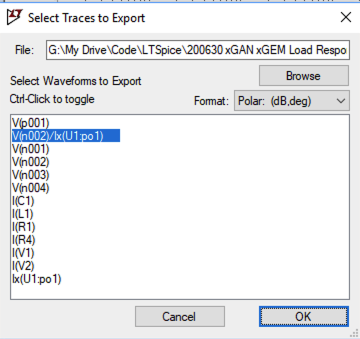

With outputs like this: 

First Line do: "Freq.	V(n002)/Ix(U1:po1)"

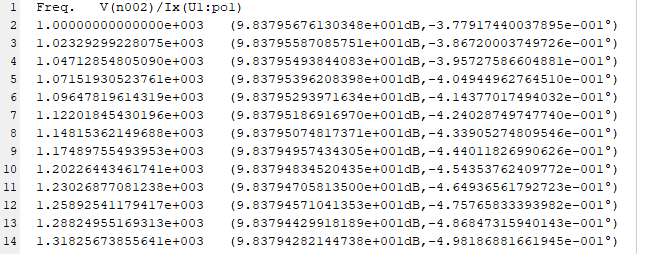

And plots it for us in MATLAB

    filenameAdd = '200701 xGAN xGEM Freq Response.txt';
    % Single line version exports just raw frequency respnse
    % !!!!!!! Must replace top line with 'Freq.	V(n002)/Ix(U1:po1)' !!!!!!!!!
    Data = LT_Freq2Table(filenameAdd)
    % Data = table2array(Data);
    freq = Data(:,'Freq');
    MagZ_out_dB = Data(:,'n002');
    AngZ_out = Data(:,'U1po1');
    freq = table2array(freq);
    MagZ_out_dB = table2array(MagZ_out_dB);
    AngZ_out = table2array(AngZ_out);
    MagZ_out = 10.^(MagZ_out_dB/20)
    
    loglog(freq, (MagZ_out))
    
    samplePt = 1001; %pt 1001 = 100MHz = 124.78298 ohm directly
    freqSample = freq(samplePt)
    zSample = MagZ_out(samplePt) % convert from dB to normal!s
    % z = 1/(2pi*f*C)lead to
    C_eff = 1/(2*pi*freqSample*abs(zSample))
    
    resFreq = 1.0694652e9; %GHz
    % w^2 = 1/LC
    L_eff = 1/((2*pi*resFreq)^2*C_eff)
    save('200701 xGAN Kimball RLC Full Freq Resp', 'freq', 'MagZ_out')
    
    
end